# The Fast Fourier Transform

Fourier transforms are frequently used to examine observational and experimental data. However, because data are sampled at discrete intervals, these techniques use a *discrete Fourier Transform *to decompose a signal into frequencies. The algorithm used most often for this is called the *Fast Fourier Transform* that was invented by James Cooley and John Tukey. In this sheet we will look some uses of the Fourier Transform for understanding data. 

## The Sine Function

The idea behind the Fourier Transform is that it allows you to examine a signal in *frequency space* as opposed to time. This allows you to see the frequencies that make up the signal — something that can be hard to do by looking at the data alone. Let's start with a very simple case, a single sine wave with a single frequency. 

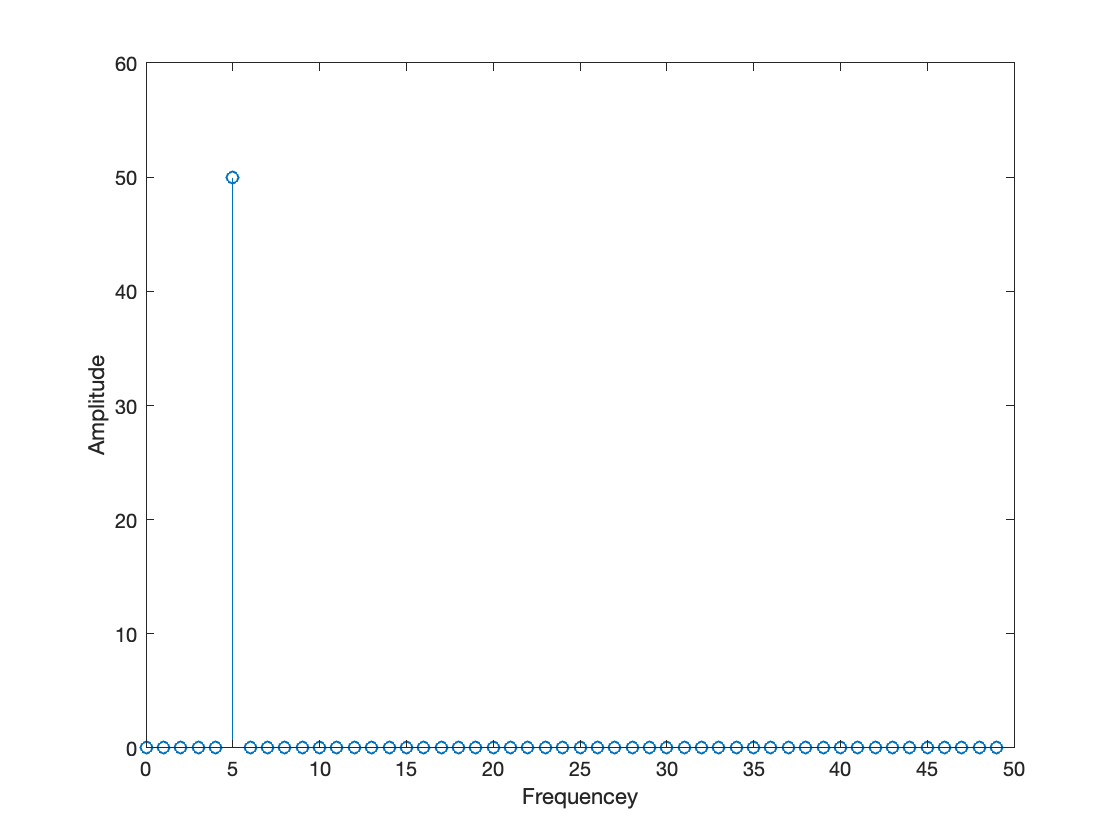

% Define the frequncy of the signal
signal_freq = 5;

% Define the rate at which the data is sampled (e.g. 100Hz if the original
% signal is in seconds, or 1 per hour if the time is measured in hours
% etc.) and set up a vector sampling times at that frequency.
sample_rate  = 100;
sample_times = 0 : 1/sample_rate : 1 - 1/sample_rate;
n_samples    = length(sample_times);

% Create the signal, in this case a single sine wave with an amplitude of 1
% and a frequency of signal_freq.
signal_data = sin(2*pi*signal_freq*sample_times);

% Calculate the discrete Fourier transform using the Fast Fourier Transform
fft_signal = fft(signal_data);

% Create a vector of frequencies
f = (0:n_samples-1)/(n_samples / sample_rate);

% Because the Fast Fourier Transform works with complex numbers (remember
% Euler's formula connecting sines and cosines with complex numbers), it
% produces twice as much information as we need. So we only plot half the
% FFT and, again because we are working with complex numbers, we plot the
% magnitude of the FFT
figure
stem(f(1:n_samples/2), abs(fft_signal(1:n_samples/2)))
xlabel('Frequencey')
ylabel('Amplitude')

The FFT produces a *frequency spectrum* which shows us which frequencies contrinute to the signal. It also gives us a measure of the strength of the signal at that frequency. We can see from the plot that the only signal has a frequency of 5, which is how we set up the data. 

***Exercise:**** Calculate and plot the Fourier Transform of the following signals and comment on the results*

*a) *$y(t) = cos(2\pi\times 15 \times t)$  b) $y(t) = 20\sin(2\pi\times 6t) + 5\cos(2\pi\times 13t)$

## The Square Wave

The signal does not have to be smooth. For example, we can calculate the FFT of a square wave signal

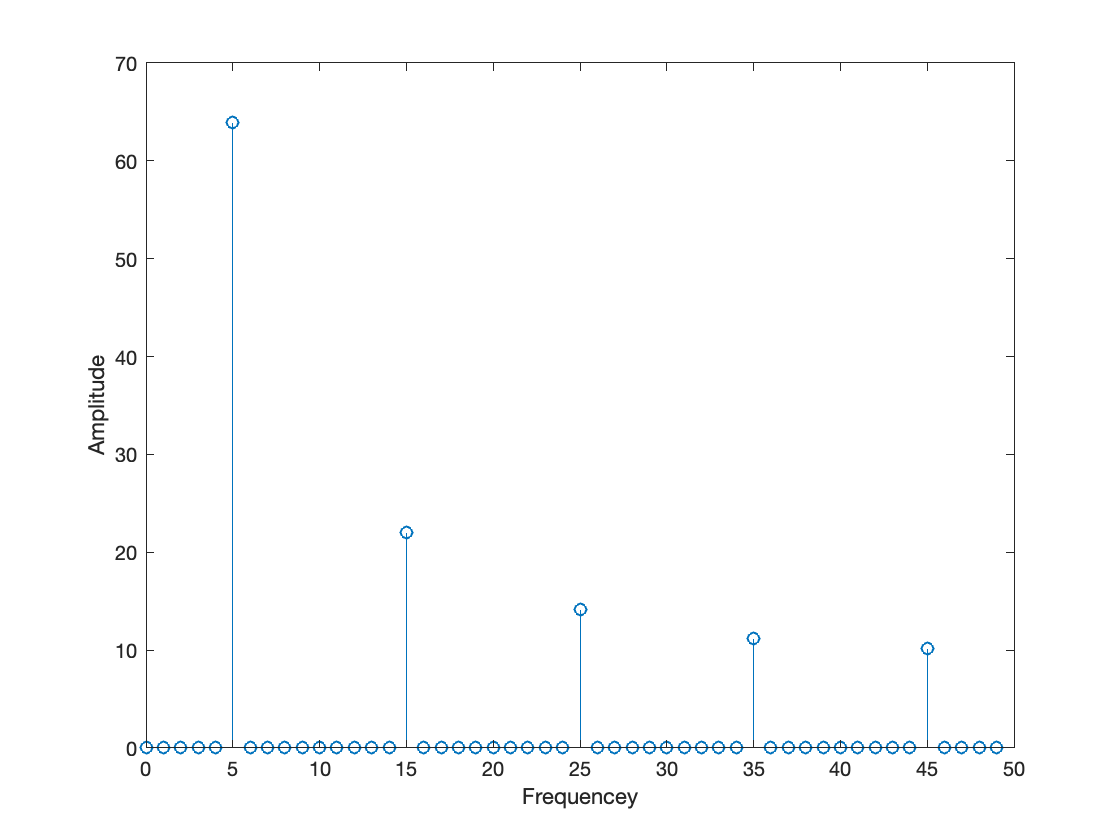

signal_freq = 5;
sample_rate = 100;
sample_times = 0 : 1/sample_rate : 1 - 1/sample_rate;
n_samples = length(sample_times);

signal_data = square(2*pi*signal_freq*sample_times);

fft_signal = fft(signal_data);

f = (0:n_samples-1)/(n_samples / sample_rate);
figure
stem(f(1:n_samples/2), abs(fft_signal(1:n_samples/2)))
xlabel('Frequencey')
ylabel('Amplitude')

Here we see something interesting: we not only get a signal at the frequency we used to create the signal (5), but also higher frequencies. These arise because the signal has sharp edges and we need more and more higher frequencies to represent these, as was shown in Chapter 9.

## Tide Gauge Data

Let's apply the same technique to some real world Earth data. In this case we will use tide gauge data measured at Fort Pulaski, Georgia, USA. This data is part of a US NOAA monitoring program and the data are freely available from [https://tidesandcurrents.noaa.gov/stationhome.html?id=8670870.](https://tidesandcurrents.noaa.gov/stationhome.html?id=8670870.) For this example, we have already downloaded the data and stored it in a file `pulaski_tidal_data2.dat. `

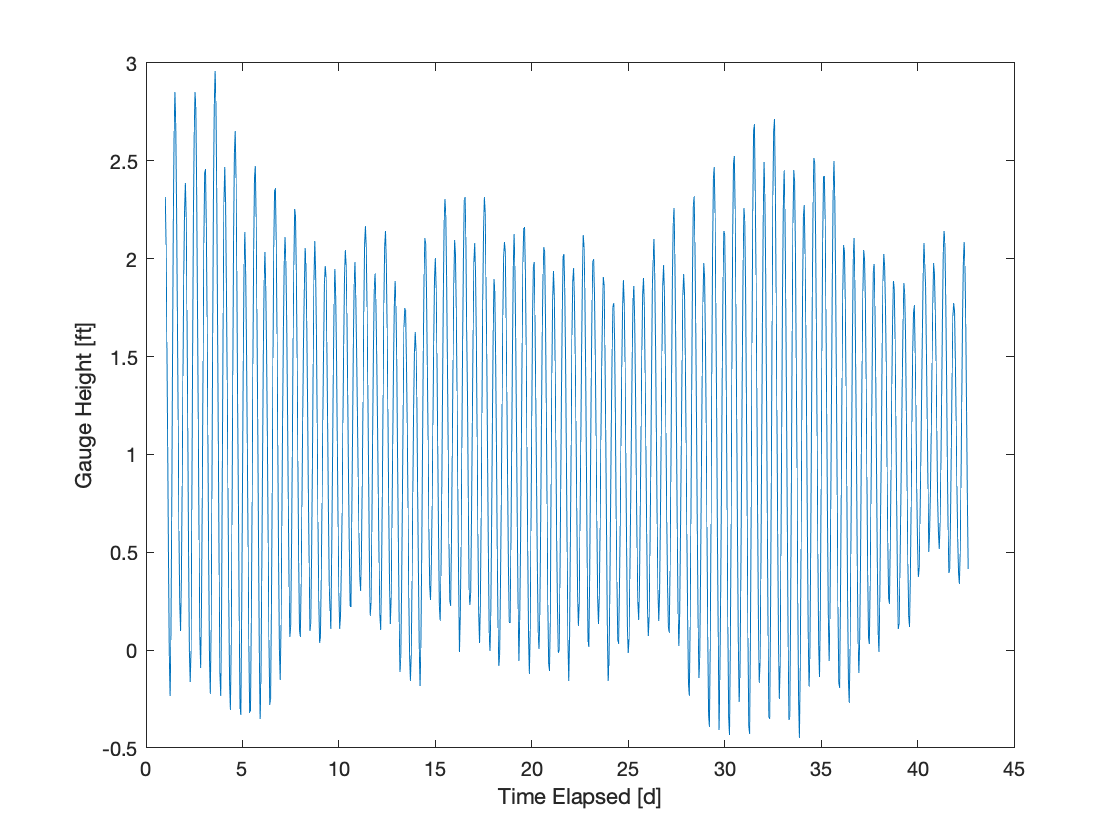

% First load the data and put the first column into a vector of times and
% the second into a vector of gauge heights. 
load pulaski_tidal_data2.dat

t            = pulaski_tidal_data2(:,1);
gauge_height = pulaski_tidal_data2(:,2);

% Plot the data — this is something tou should ALWAYS do in any analysis of
% data.
figure
plot(t, gauge_height)
xlabel('Time Elapsed [d]')
ylabel('Gauge Height [ft]')

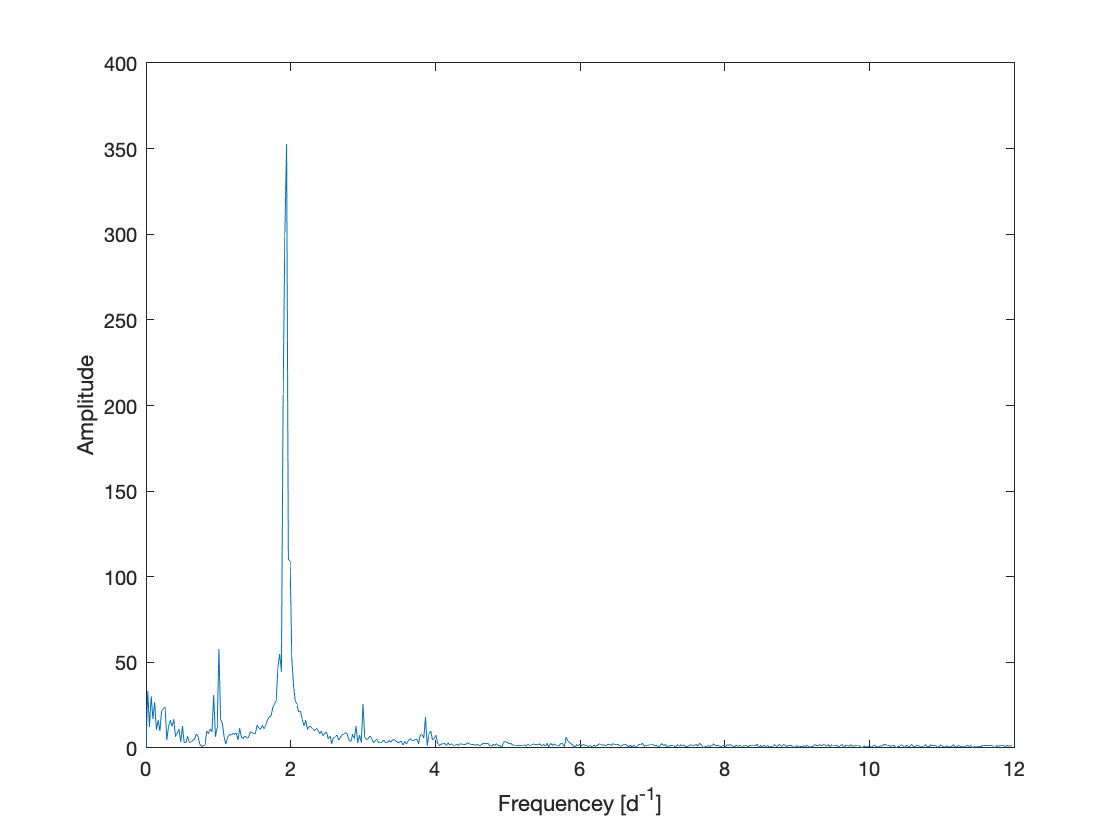


% Calculate the sampling frequency vector using the mean time interval in
% the data
delta_t    = mean(diff(t));
N          = length(gauge_height);
delta_freq = 1/(N * delta_t);

f = (0:N-1)*delta_freq;

% Calculate the FFT
ftide = fft(gauge_height - mean(gauge_height));

% Plot the FFT
figure
plot(f(1:N/2), abs(ftide(1:N/2)))
xlabel('Frequencey [d^{-1}]')
ylabel('Amplitude')

We can see that the dominant signal has a frequency of approximately 2 per day, which is the dominant tide in this region. There are also higher order harmonics (parts of the signal occurring at different frequencies) and lower order harmonics. 

***Execise:**** What do you think might be causes of these higher and lower order harmonics in the signal?* 